# Estimations Parameters from PISCO data

Jess Hopf

jess.k.hopf@gmail.com

### Required scrips: 

- Functions/Func_ReadSmurfData

### Objectives

- To estimate variation in the density of new recruits (pre- and post- density-dependence) from data

- To fit a distribution describing the sampling process of adults to data

### Data:

- SMURF data: PISCO_UCSB_subtidal_recruitment_fish_data.1.2.csv (up to 2018)

- YOY data: PISCO_kelpforest_fish.1.3.csv (focus on Channel Islands; up to 2018)

- Adult data: PISCO_kelpforest_fish.1.3.csv (focus on Pt Lobos; up to 2018)

# SMURF Data - Channel Islands

SMURF data estimates the densities of incoming larvae, pre densitiy dependent processes. 

## Blue Rockfish

Study species is Blue Rockfish (Sebastes mystinus, SMYS). We'll look at what SMURF data exists for them. 

#### 1. Set Up & Read-in Data

clear
addpath('.\Functions')
addpath('.\PISCOData_20230125')

% Read in data for Blue Rockfish 
SMURFdata = Func_ReadSmurfData("PISCO_UCSB_subtidal_recruitment_fish_data.1.2.csv",'SMYS');


% Order
SMURFdata = sortrows(SMURFdata,{'Island', 'SITE','Year'});

#### 2. Exploratory Plots

By Island

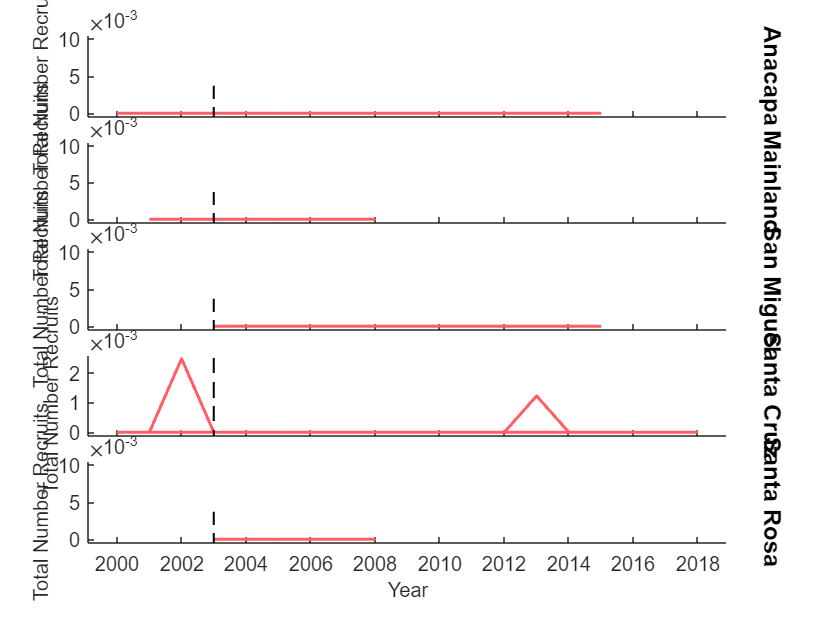

SMURFdata = convertvars(SMURFdata,{'Species','Island','SITE'},'categorical');

SMURFdataT = SMURFdata(:,{'Species','Year','Island','NumFishSt'});
clear g
figure();
g = gramm('x',SMURFdataT.Year,'y',SMURFdataT.NumFishSt);
g.geom_line();
% g.stat_summary('type','std','geom','area');
g.facet_grid(SMURFdataT.Island,[],"scale","free_y");
g.set_names('x','Year','y','Total Number Recruits','row','');
g.geom_vline('xintercept',2003);
g.draw();

All together (pooled across islands)

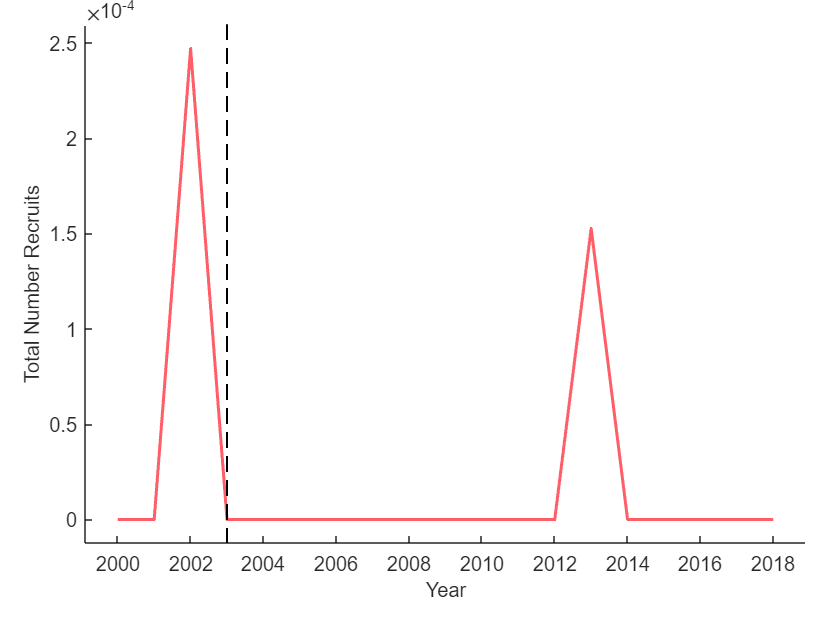

% Total count
SMURFdataT = grpstats(SMURFdata,{'Year'},'mean','DataVars','NumFishSt');
clear g
figure();
g = gramm('x',SMURFdataT.Year,'y',SMURFdataT.mean_NumFishSt);
g.geom_line();
% g.stat_summary('type','sem','geom','area');
g.set_names('x','Year','y','Total Number Recruits');
g.geom_vline('xintercept',2003);
g.draw();

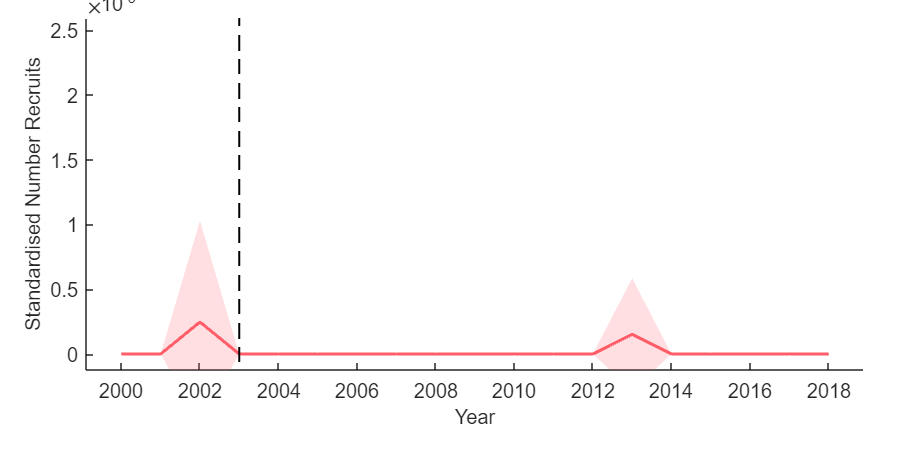

% mean and std
clear g
figure('Position',[10,10,600,300]);
g = gramm('x',SMURFdata.Year,'y',SMURFdata.NumFishSt);
g.stat_summary('type','std','geom','area');
g.set_names('x','Year','y','Standardised Number Recruits','row','');
g.geom_vline('xintercept',2003);
g.draw();

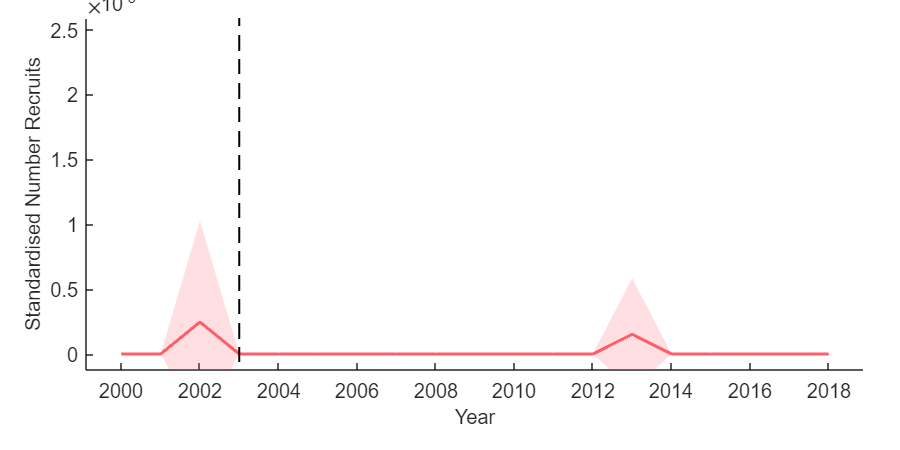

% log + 1 transformed
clear g
figure('Position',[10,10,600,300]);
g = gramm('x',SMURFdata.Year,'y',log(SMURFdata.NumFishSt+1));
g.stat_summary('type','std','geom','area');
g.set_names('x','Year','y','Standardised Number Recruits','row','');
g.geom_vline('xintercept',2003);
g.draw();

**Note: **Blue rockfish only occur twice and in very low numbers. Data is not helpful. Try another species. 

## KGBC

Using aggregated Kelp, Gopher, Black & Yellow, and Copper Rockfish (KGBC) as a proxy.

#### 1. Set Up & Read-in Data

clear
addpath('.\Functions')
addpath('.\PISCOData_20230125')

% Read in data for KGBC
SMURFdata = Func_ReadSmurfData("PISCO_UCSB_subtidal_recruitment_fish_data.1.2.csv",'KGBC');


% Order
SMURFdata = sortrows(SMURFdata,{'Island', 'SITE','Year'});

#### 2. Exploratory Plots

By Island

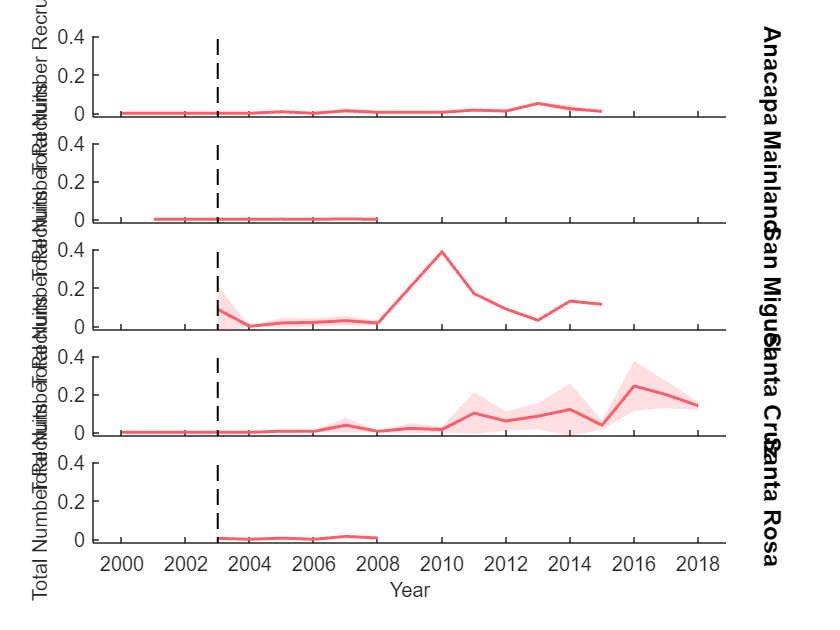

Less than 2 samples for CI computation...Skipping
Less than 2 samples for CI computation...Skipping
Less than 2 samples for CI computation...Skipping
Less than 2 samples for CI computation...Skipping
Less than 2 samples for CI computation...Skipping
Less than 2 samples for CI computation...Skipping
Less than 2 samples for CI computation...Skipping
Less than 2 samples for CI computation...Skipping


% mean and std
SMURFdata = convertvars(SMURFdata,{'Species','Island','SITE'},'categorical');

SMURFdataT = SMURFdata(:,{'Species','Year','Island','NumFishSt'});
clear g
figure();
g = gramm('x',SMURFdataT.Year,'y',SMURFdataT.NumFishSt);
% g.geom_line();
g.stat_summary('type','std','geom','area');
g.facet_grid(SMURFdataT.Island,[]);
g.set_names('x','Year','y','Total Number Recruits','row','');
g.geom_vline('xintercept',2003);
g.draw();

All together (pooled across islands)

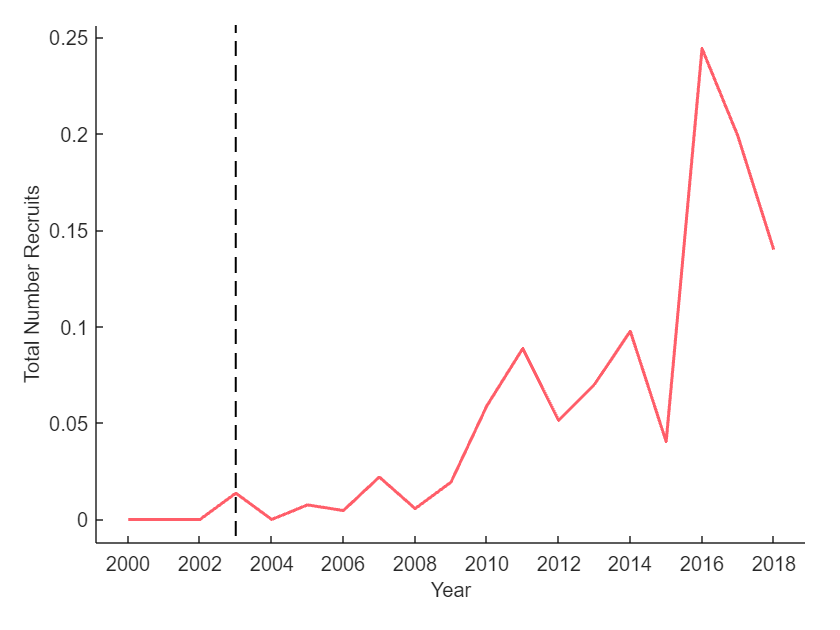

Less than 2 samples for CI computation...Skipping
Less than 2 samples for CI computation...Skipping
Less than 2 samples for CI computation...Skipping
Less than 2 samples for CI computation...Skipping
Less than 2 samples for CI computation...Skipping
Less than 2 samples for CI computation...Skipping
Less than 2 samples for CI computation...Skipping
Less than 2 samples for CI computation...Skipping
Less than 2 samples for CI computation...Skipping
Less than 2 samples for CI computation...Skipping
Less than 2 samples for CI computation...Skipping
Less than 2 samples for CI computation...Skipping
Less than 2 samples for CI computation...Skipping
Less than 2 samples for CI computation...Skipping
Less than 2 samples for CI computation...Skipping
Less than 2 samples for CI computation...Skipping
Less than 2 samples for CI computation...Skipping
Less than 2 samples for CI computation...Skipping
Less than 2 samples for CI computation...Skipping


% total number
SMURFdataT = grpstats(SMURFdata,{'Year'},'mean','DataVars','NumFishSt');
clear g
figure();
g = gramm('x',SMURFdataT.Year,'y',SMURFdataT.mean_NumFishSt);
% g.geom_line();
g.stat_summary('type','std','geom','area');
g.set_names('x','Year','y','Total Number Recruits');
g.geom_vline('xintercept',2003);
g.draw();

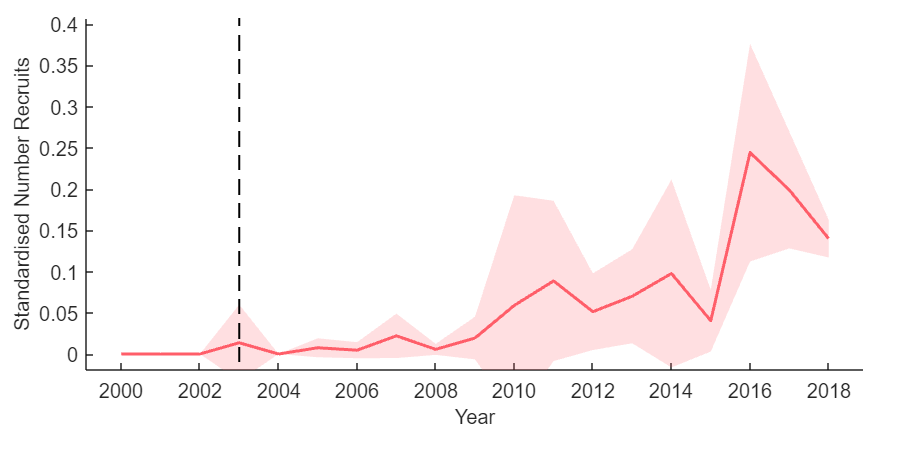

% mean and std
clear g
figure('Position',[10,10,600,300]);
g = gramm('x',SMURFdata.Year,'y',SMURFdata.NumFishSt);
g.stat_summary('type','std','geom','area');
g.set_names('x','Year','y','Standardised Number Recruits','row','');
g.geom_vline('xintercept',2003);
g.draw();

Focus on just Santa Cruz island, as density is highest there. 

% get just for santa cruz
SMURFSC = SMURFdata(SMURFdata.Island == "Santa Cruz",:);
% plot sites over time
clear g
figure();
g = gramm('x',SMURFSC.Year,'y',SMURFSC.NumFishSt,'color', SMURFSC.SITE);
g.geom_line();
g.set_names('x','Year','y','Total Number Recruits','row','');
g.geom_vline('xintercept',2003);
g.draw();

Group by north and south sites. 

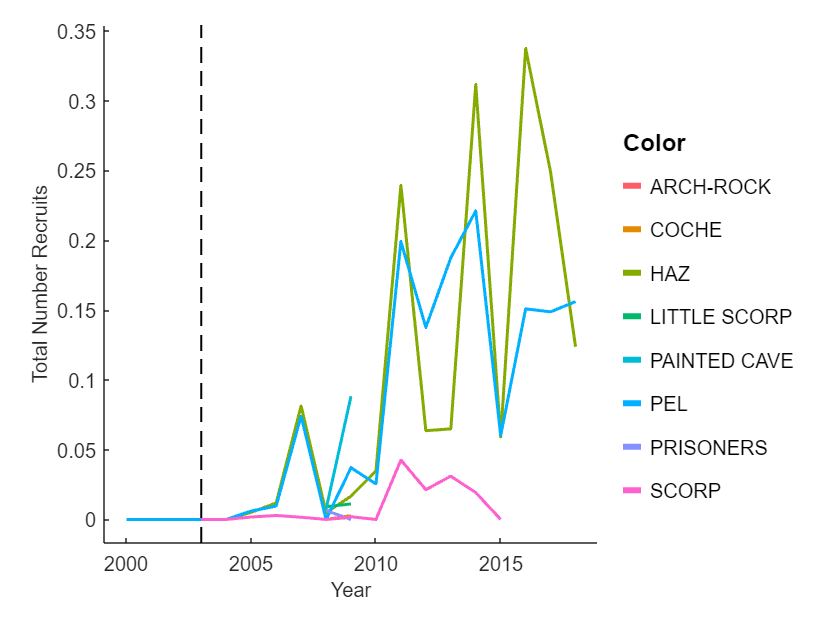

% split north and south
SITE = unique(SMURFSC.SITE);
NS = ["N","N","S","N","N","N","N","S","N","N","S","S","S","S"]';
NS_tab = table(SITE,NS);
SMURFSC = outerjoin(SMURFSC,NS_tab,"Type","left","MergeKeys",true);
SMURFSC = convertvars(SMURFSC,'NS','categorical');

% facetted
clear g
figure();
g = gramm('x',SMURFSC.Year,'y',SMURFSC.NumFishSt,'color', SMURFSC.SITE);
g.facet_grid(SMURFSC.NS,[]);
g.geom_line();
g.set_names('x','Year','y','Total Number Recruits','row','');
g.geom_vline('xintercept',2003);
g.draw();
% individual
SMURFSCN = SMURFSC(SMURFSC.NS == "N",:);
SMURFSCS = SMURFSC(SMURFSC.NS == "S",:);

clear g
figure();
g = gramm('x',SMURFSCN.Year,'y',SMURFSCN.NumFishSt,'color', SMURFSCN.SITE);
g.geom_line();
g.set_names('x','Year','y','Total Number Recruits','row','');
g.geom_vline('xintercept',2003);
g.draw();

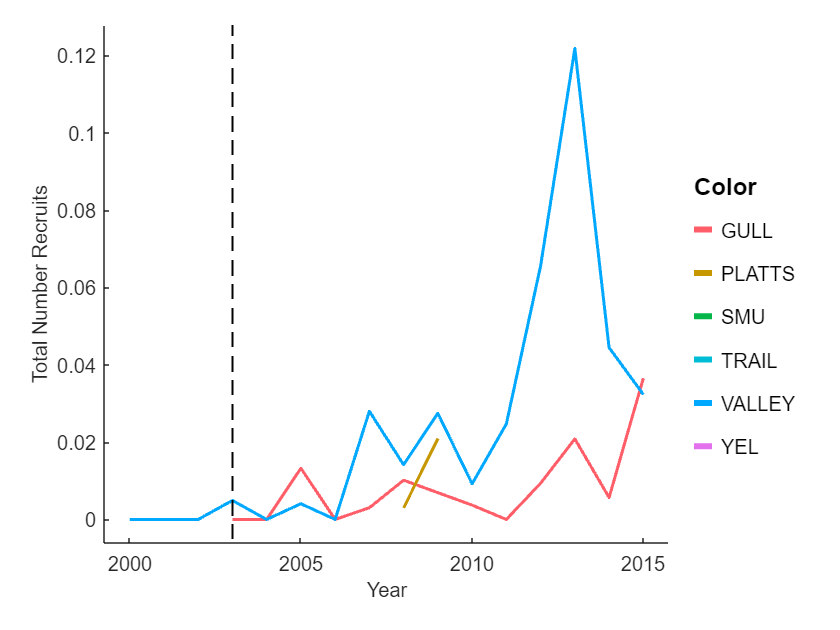


clear g
figure();
g = gramm('x',SMURFSCS.Year,'y',SMURFSCS.NumFishSt,'color', SMURFSCS.SITE);
g.geom_line();
g.set_names('x','Year','y','Total Number Recruits','row','');
g.geom_vline('xintercept',2003);
g.draw();

### Estimate variance 

Using KGBC at Northern Santa Cruz sites.

#### 1. Detrend the data

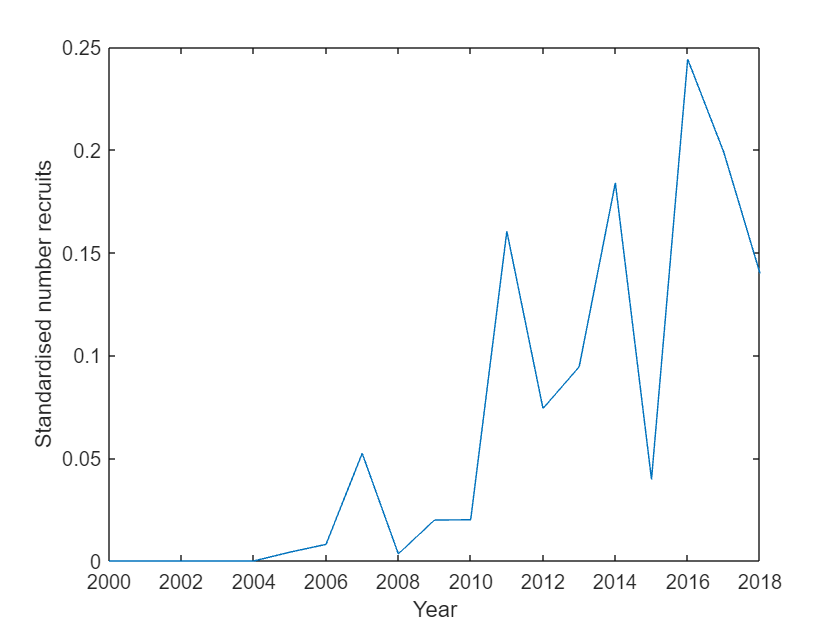

% choose data:
    % grouping across sites in north or south (sums across all transects in a site)
    % north:
    TSdata = grpstats(SMURFSCN(:,{'Species','Year','NumFishSt'}), ...
                               {'Species','Year'},'sum');

    % standardise by number of sites in a given year
    TSdata.NormNumFishSt = TSdata.sum_NumFishSt./TSdata.GroupCount;
    
    % chose variable to use
    TSdata.Data = TSdata.NormNumFishSt;
    
    figure
    plot(TSdata.Year, TSdata.Data)
    xlabel("Year")
    ylabel("Standardised number recruits")

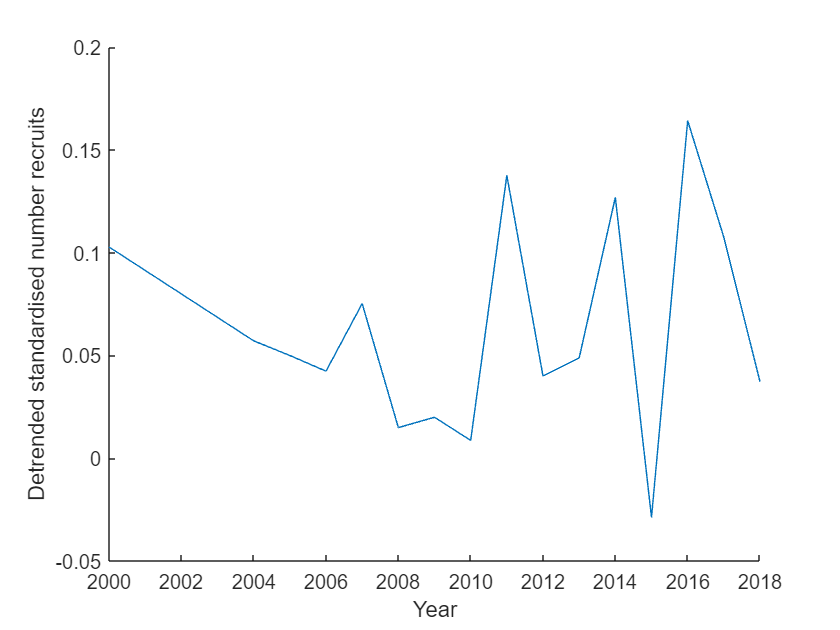


% detrend:
    % fit linear model
    Model = fitglm(TSdata.Year, TSdata.Data);
    
    % mean plus the redsiduals 
    % (difference between the observed and values predicted by the fitted model)
    tsDT = mean(TSdata.Data) + TSdata.Data - predict(Model,TSdata.Year);
    
% plot
figure
hold on
plot(TSdata.Year, tsDT)
xlabel("Year")
ylabel("Detrended standardised number recruits")

#### 2. Normalise and scale

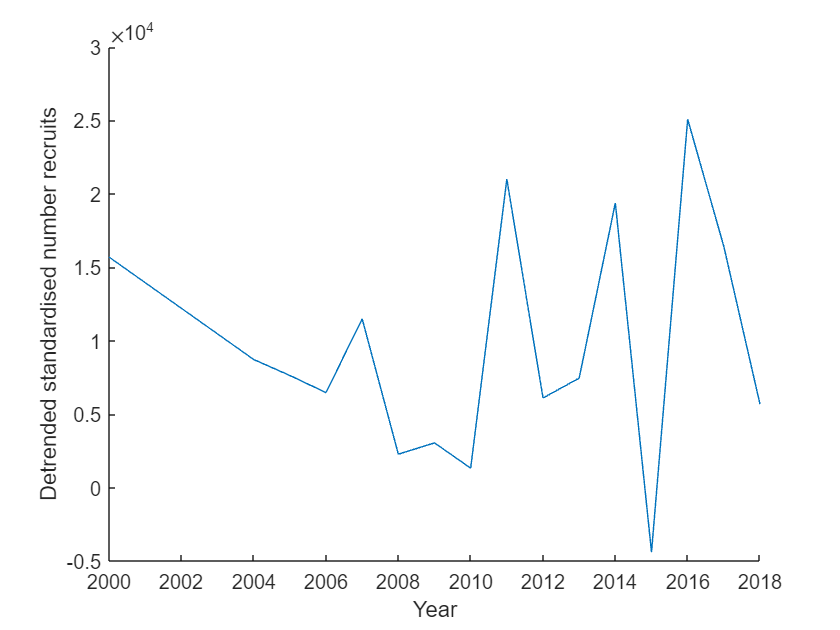

   
% normalise and then scale to avg incoming larvae set in model
    tsDTnorm = tsDT./mean(tsDT);
    tsDTnormnorm = tsDTnorm*10^4;

figure
hold on
plot(TSdata.Year, tsDTnormnorm)
xlabel("Year")
ylabel("Detrended standardised number recruits")    

#### 3. Get variance

std(tsDT)

ans = 0.0484

std(tsDTnorm)

ans = 0.7395

std(tsDTnormnorm)

ans = 7.3952e+03

# YOY - Channel Islands 

Looking at young-of-year (YOY) recrtuits to see if we can estimate variability in post-DD recrtuiment. 

## KGBC

PISCO_kelpforest_taxon_table.1.2.csv says that "KGB" is "Kelp, Gopher, Black And Yellow, and Copper Rockfish **Young of Year**"

#### 1. Set Up & Read-in Data

clear
addpath('.\Functions')
addpath('.\PISCOData_20230125')

% read in data
YOYdata = readtable('PISCO_kelpforest_fish.1.3.csv','TextType','string');

    % There are some missing data
    % these are mostly in non-important variables
    % but there are three in the the NumFish variable
%     [num2cell(sum(ismissing(YOYdata)))' YOYdata.Properties.VariableNames']
    % look at missing NumFish
%     YOYdf(ismissing(YOYdata.count),:)
    % we'll just remove these
    YOYdata = rmmissing(YOYdata,'DataVariables',{'count'});

% rename some variables
YOYdata = renamevars(YOYdata, {'site','classcode','year','count'},...
                              {'SITE','species', 'Year', 'NumFish'});

% remove some non-essential variables
YOYdata = YOYdata(:,{'Year','month','day','SITE','zone','level','transect','species','NumFish'});

% filter for KGB
YOYdata = YOYdata(YOYdata.species == "KGB",:);


Lets just look at Santa Cruz Island (to match what we did with the SMURF data)

- sites are slightly different for kelp survey to SMURF sites

- SCI_ sites are Santa Cruz

- Need to clean up sites before using - rename all sites that are close to each other to the same name (this is the same as what we did for the SMURF data)

% check the site list
% unique(YOYdata.site)

% separate first part of site code as this is the island/broader location
YOYdata_SCI = [YOYdata rowfun(@(x) strtok(x,'_'),YOYdata,'InputVariables','SITE','OutputVariableNames',{'Island','site1'})];

% rename sites that are close to same name
YOYdata_SCI = [YOYdata_SCI rowfun(@(x) strtok(reverse(x),'_'),YOYdata_SCI,'InputVariables','site1','OutputVariableNames',{'side1','site2'})];

% reverse back site names
YOYdata_SCI = [YOYdata_SCI rowfun(@(x) reverse(x),YOYdata_SCI,'InputVariables',{'site2'},'OutputVariableNames',{'site3'})];
YOYdata_SCI = [YOYdata_SCI rowfun(@(x) reverse(x),YOYdata_SCI,'InputVariables',{'side1'},'OutputVariableNames',{'side'})];

% clean up the site column
YOYdata_SCI = [YOYdata_SCI rowfun(@(x) strip(x,'_'),YOYdata_SCI,'InputVariables','site3','OutputVariableNames','site')];

% remove no longer needed colums 
YOYdata_SCI = removevars(YOYdata_SCI,{'SITE', 'site1', 'site2', 'site3','side1'});

% pulling out SCI_sites
YOYdata_SCI = YOYdata_SCI(strncmp(YOYdata_SCI.Island, "SCI", 4),:);

% convert relevant columns
YOYdata_SCI = convertvars(YOYdata_SCI,{'Island','site','site'},'categorical');


Data has site (inc. multiple of same site with sides) -> zone -> level -> transect. We will treat each site/side/zone/level/transect as a replicate. 

First sum duplicates of unique combinations within the same transect, as they are counts of different size fish 

% sum up all the fish from the same transect 
YOYdata_SCIs = grpstats(YOYdata_SCI,{'Year','site','side','zone','level','transect','species'},...
    'sum','DataVars','NumFish');

% rename
YOYdata_SCIs = renamevars(YOYdata_SCIs,"sum_NumFish","TNumFish");

% remove grouping count
YOYdata_SCIs = removevars(YOYdata_SCIs, 'GroupCount');

% get the mean for each site x year
YOYdata_SCIsMean = grpstats(YOYdata_SCIs, {'Year','site','species'},'mean','DataVars','TNumFish');


#### 2. Exploratory Plots

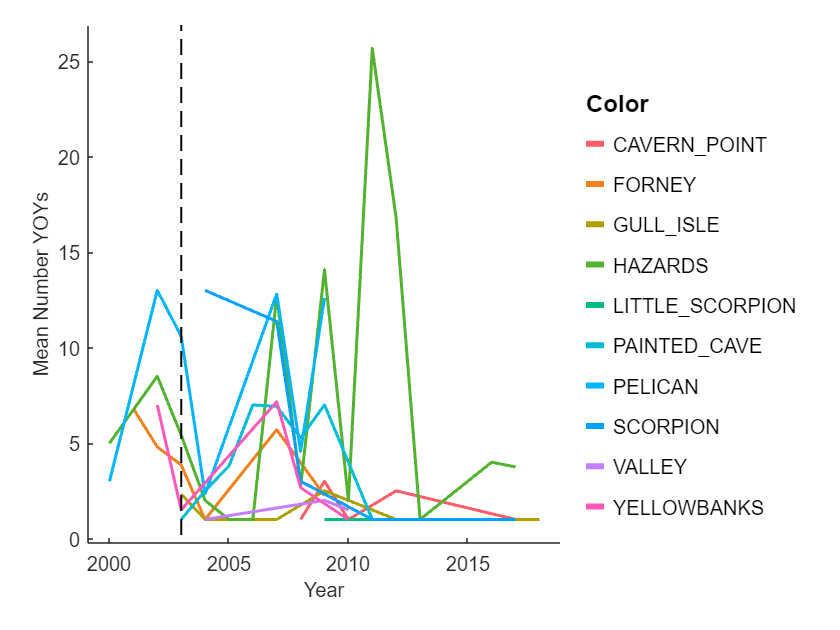

% plot all sites over time
clear g
figure();
g = gramm('x',YOYdata_SCIsMean.Year,'y',YOYdata_SCIsMean.mean_TNumFish,'color', YOYdata_SCIsMean.site);
g.geom_line();
g.set_names('x','Year','y','Mean Number YOYs','row','');
g.geom_vline('xintercept',2003);
g.draw();

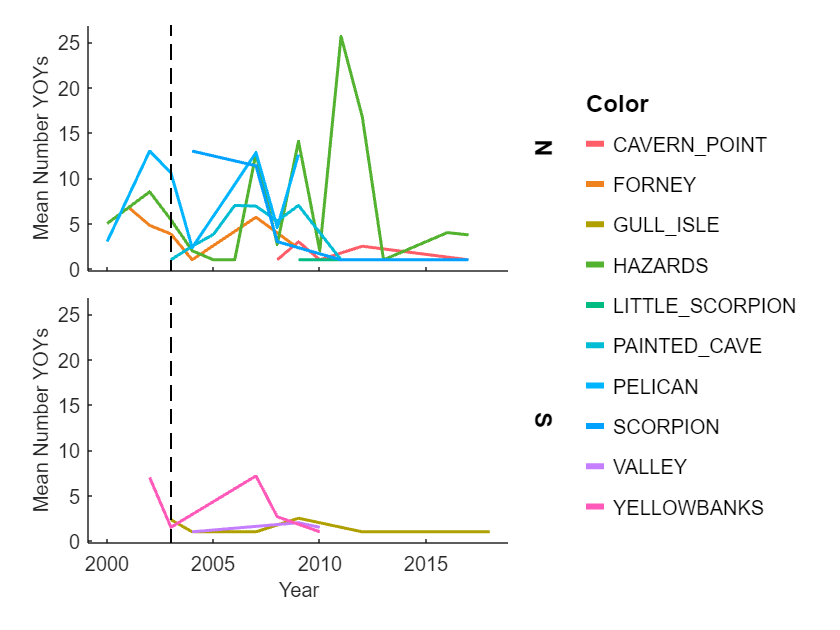


% split north and south
site = unique(YOYdata_SCIsMean.site);
NS = ["N","N","S","N","N","N","N","N","S","S"]';
NS_tab = table(site,NS);
YOYdata_SCIsMean = outerjoin(YOYdata_SCIsMean,NS_tab,"Type","left","MergeKeys",true);
YOYdata_SCIsMean = convertvars(YOYdata_SCIsMean,'NS','categorical');

clear g
figure();
g = gramm('x',YOYdata_SCIsMean.Year,'y',YOYdata_SCIsMean.mean_TNumFish,'color', YOYdata_SCIsMean.site);
g.facet_grid(YOYdata_SCIsMean.NS,[]);
g.geom_line();
g.set_names('x','Year','y','Mean Number YOYs','row','');
g.geom_vline('xintercept',2003);
g.draw();

### Finding variance

#### 1. Detrend the data

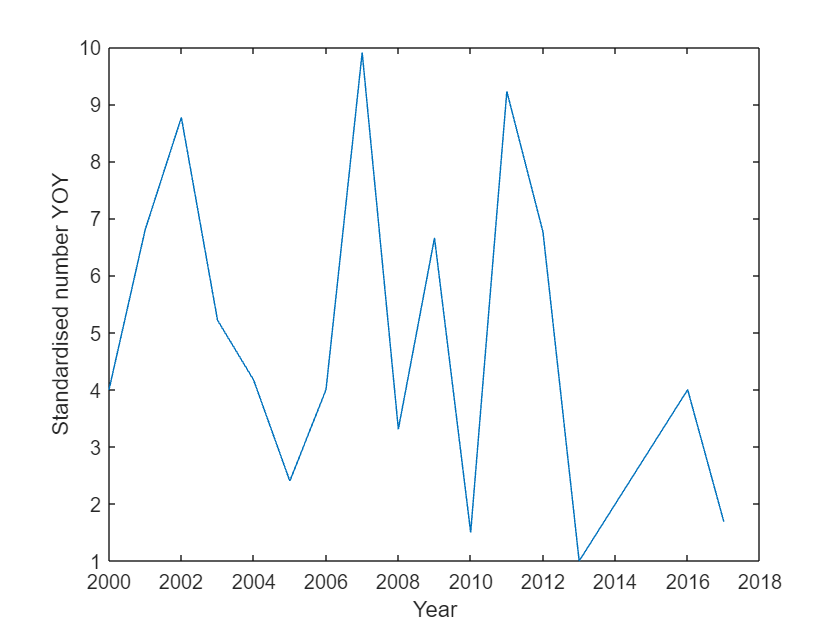

% choose data:
    % pool across sites in north 
    TSdata = grpstats(YOYdata_SCIsMean(YOYdata_SCIsMean.NS == "N",{'species','Year','mean_TNumFish'}), ...
                               {'species','Year'},'sum');

    % standardise by number of sites in a given year
    TSdata.NormNumFishSt = TSdata.sum_mean_TNumFish./TSdata.GroupCount;
    
    % chose variable to use
    TSdata.Data = TSdata.NormNumFishSt;
    
    figure
    plot(TSdata.Year, TSdata.Data)
    xlabel("Year")
    ylabel("Standardised number YOY")

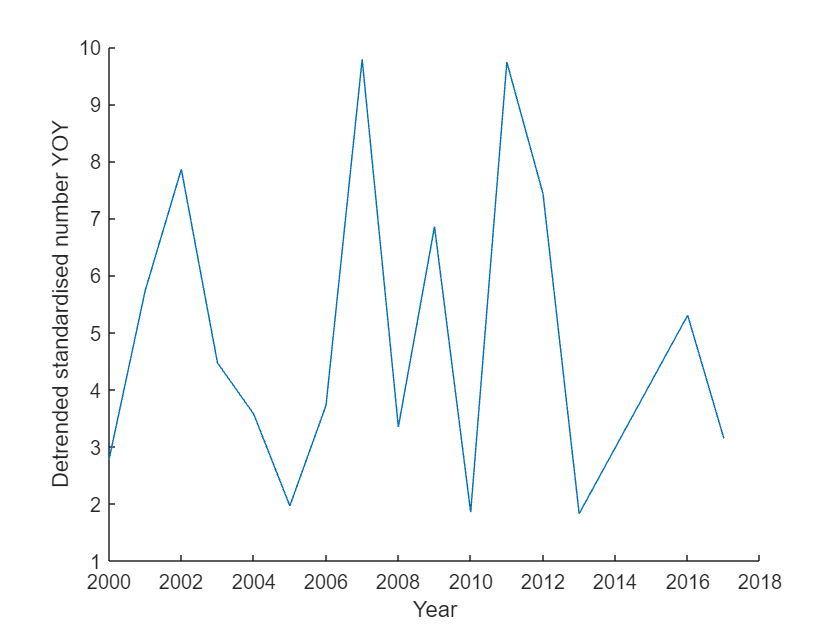


% detrend:
    % fit linear model
    Model = fitglm(TSdata.Year, TSdata.Data);
    
    % mean plus the redsiduals 
    % (difference between the observed and values predicted by the fitted model)
    tsDT = mean(TSdata.Data) + TSdata.Data - predict(Model,TSdata.Year);
    
% plot
figure
hold on
plot(TSdata.Year, tsDT)
xlabel("Year")
ylabel("Detrended standardised number YOY")

#### 2. Normalise and scale

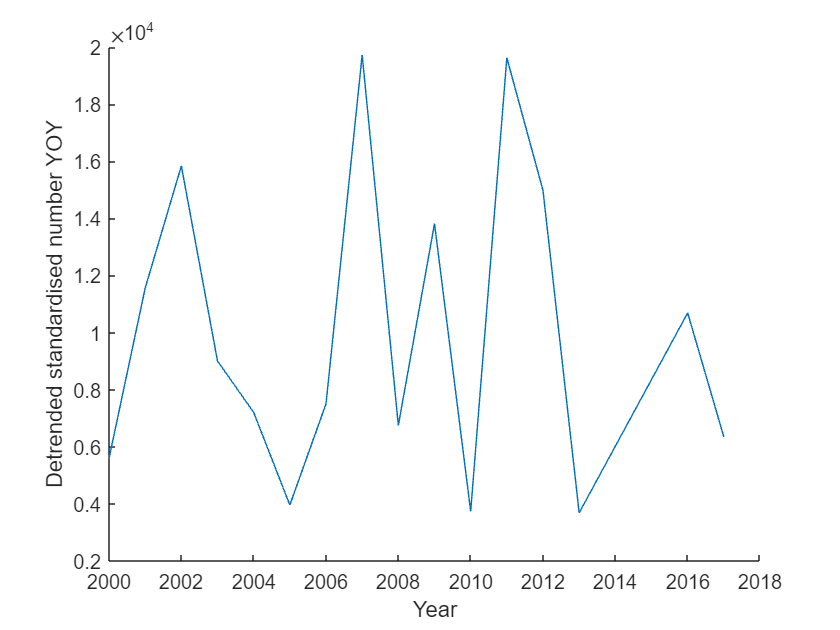

% normalise and then scale to avg incoming larvae set in model
    tsDTnorm = tsDT./mean(tsDT);
    tsDTnormnorm = tsDTnorm*10^4;

figure
hold on
plot(TSdata.Year, tsDTnormnorm)
xlabel("Year")
ylabel("Detrended standardised number YOY")    

#### 3. Get variance

std(tsDT)

ans = 2.6789

std(tsDTnorm)

ans = 0.5399

std(tsDTnormnorm)

ans = 5.3990e+03

**Notes: **

- Variance is not too different between pre-DD and post-DD. Used post-DD value in model

# Fitting sampling distribution 

- Fit a distribution to the data to estimate measurement error.

- Using adult Blue Rockfish data for California

#### 1. Setup and read-in data

clear
addpath('.\Functions')
addpath('.\PISCOData_20230125')

% read in data
FishData = readtable('PISCO_kelpforest_fish.1.3.csv','TextType','string');

    % There are some missing data
    % these are mostly in non-important variables
    % but there are three in the the count variable
%     [num2cell(sum(ismissing(FishData)))' FishData.Properties.VariableNames']
    % look at missing NumFish
%     FishData(ismissing(FishData.count),:)
    % we'll just remove these, they are irrelevant 
    FishData = rmmissing(FishData,'DataVariables',{'count'});

% rename some variables
FishData = renamevars(FishData, {'site','classcode','year','count'},...
                              {'SITE','species', 'Year', 'NumFish'});

% remove some non-essential variables
FishData = FishData(:,{'Year','SITE','zone','level','transect','species','NumFish','fish_tl'});

% filter for SMYS
FishData = FishData(FishData.species == "SMYS",:);


Lets just look at  Pt Lobos - there are more blue rockfish there

- Pt Lobos sites: "BIXBY",  "BLUEFISH_DC", "BLUEFISH_UC", "MALPASO", "MONASTERY_DC", "MONASTERY_UC", "PALO_COLORADO", "SOBERANES", "WESTON_DC", "WESTON_UC"

- Need to clean up sites before using - rename all sites that are close to each other to the same name 

% check the site list
% unique(FishData.SITE)

% pull out required sites
FishData_PL = FishData(contains(FishData.SITE, ["BIXBY", "BLUEFISH_DC","BLUEFISH_UC", "MALPASO", "MONASTERY_DC", "MONASTERY_UC", "PALO_COLORADO", "SOBERANES", "WESTON_DC", "WESTON_UC"]),:);

% pool all size classes

FishData_PLs = grpstats(FishData_PL, {'Year','SITE','zone','level','transect'}, 'sum', 'DataVars','NumFish');
% rename
FishData_PLs = renamevars(FishData_PLs,"sum_NumFish","TNumFish");

% remove grouping count
FishData_PLs = removevars(FishData_PLs, 'GroupCount');

### Fit neg binomial dist

- first assume all transects independent (ignore year-to-year aspect)

- Variance is much greater than mean, so Poisson is not suitable. 

### summary stats 

% get vector of counts
SMYScounts = FishData_PLs.TNumFish;

% find mean and variance
mu = mean(SMYScounts)

mu = 19.0022

v = var(SMYScounts)

v = 779.3560

Variance definately greater than mean!

### fit neg binomial distribution

#### 1. all years pooled together.

% R = k (clumping) <- this is the one we want
% P = R/(mean + R)  
% mean = (R/P) - R

% fit distriution
pd1 = fitdist(SMYScounts,'nbin')

pd1 =   NegativeBinomialDistribution

  Negative Binomial distribution
    R =  0.750369   [0.713848, 0.786891]
    P = 0.0379885   [0.0355944, 0.0403826]


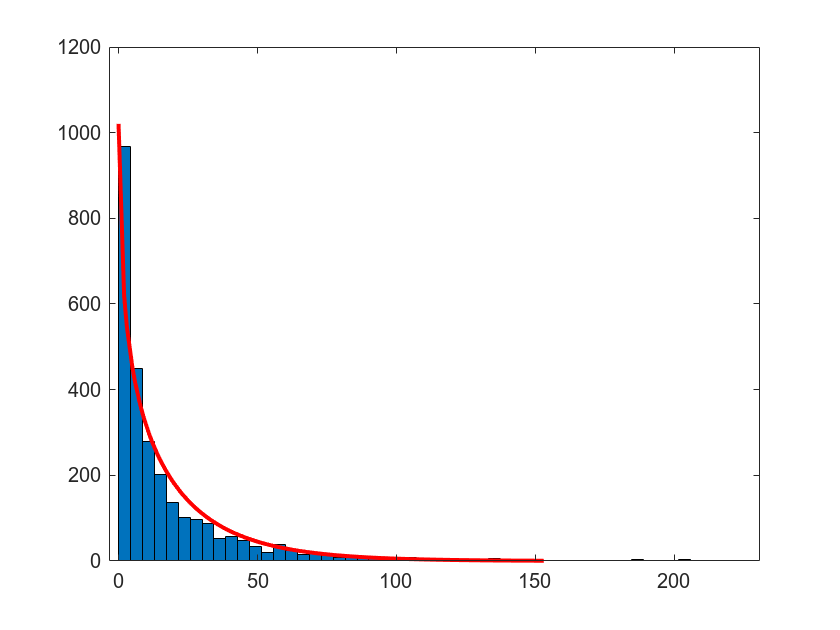

% plot
figure
histfit(SMYScounts,[],"nbin")


% NLL value
NLL1 = pd1.negloglik

NLL1 = 1.0920e+04

pd1.mean

ans = 19.0022

pd1.var

ans = 500.2085

#### 2. by year

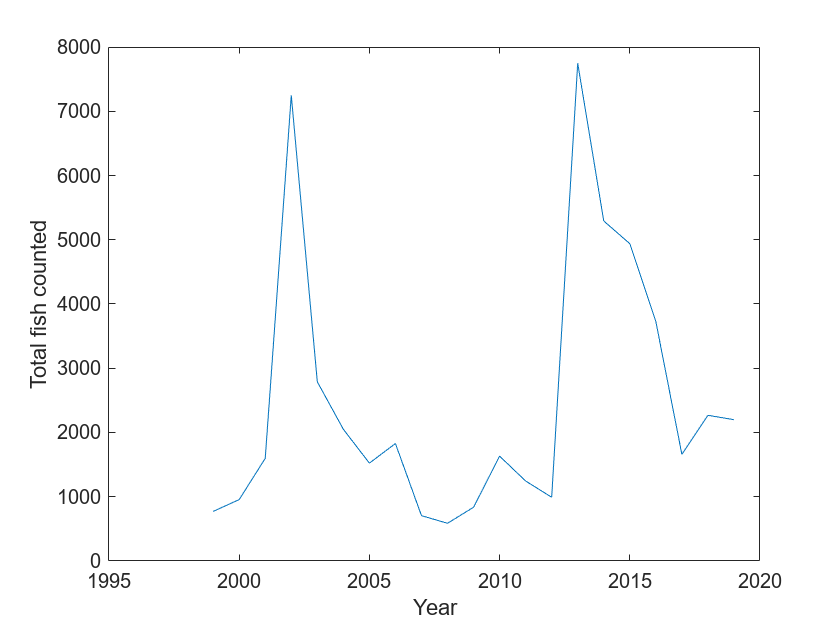

% plot total over time
fishYrs = grpstats(FishData_PLs,"Year", {'sum','mean'},'DataVars','TNumFish');
figure
plot(fishYrs.Year,fishYrs.sum_TNumFish)
ylabel('Total fish counted')
xlabel('Year')

% fit distriution for each year
pdyear= fitdist(SMYScounts,'nbin','By',FishData_PLs.Year);

Kyrs = zeros(1,21);
for i = 1:length(Kyrs)
    Kyrs(i) = pdyear{i}.R;
    NLLyrs(i) = pdyear{i}.negloglik;
end

% comparable fit to all years (~NLL1 = 1.092+04)
sum(NLLyrs)

ans = 1.0402e+04


% summary stats
[mean(Kyrs), min(Kyrs), max(Kyrs), std(Kyrs)]

ans =     1.0594    0.7852    2.0142    0.2755


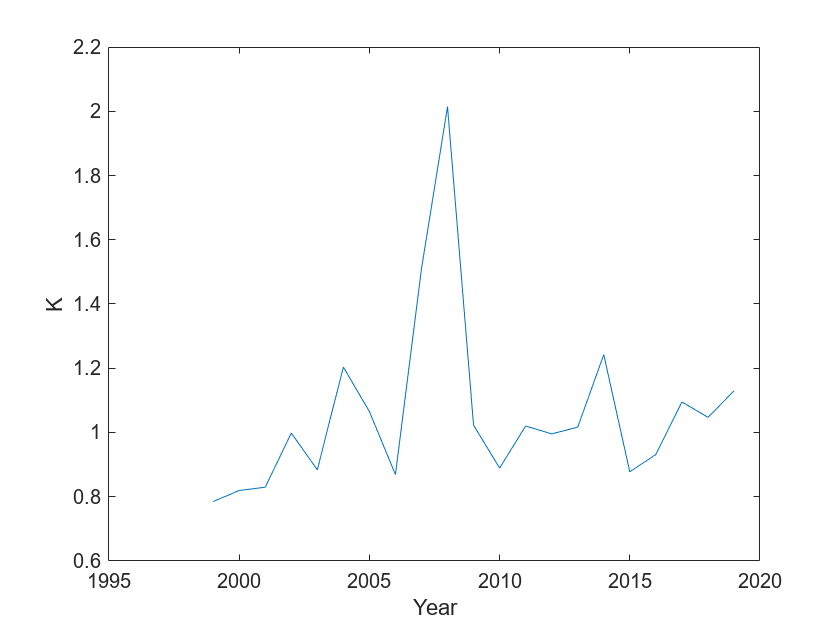


figure
plot(fishYrs.Year, Kyrs)
ylabel('K')
xlabel('Year')

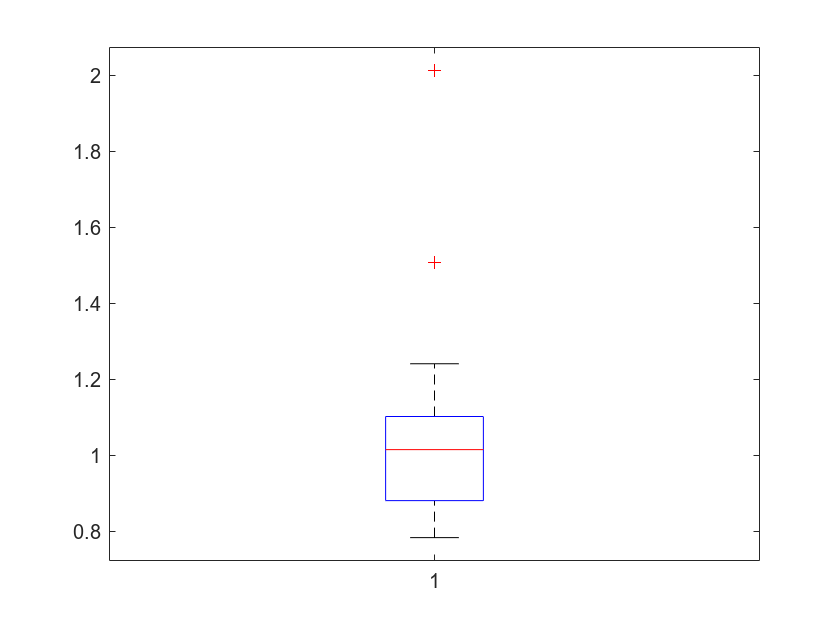

figure
boxplot(Kyrs)

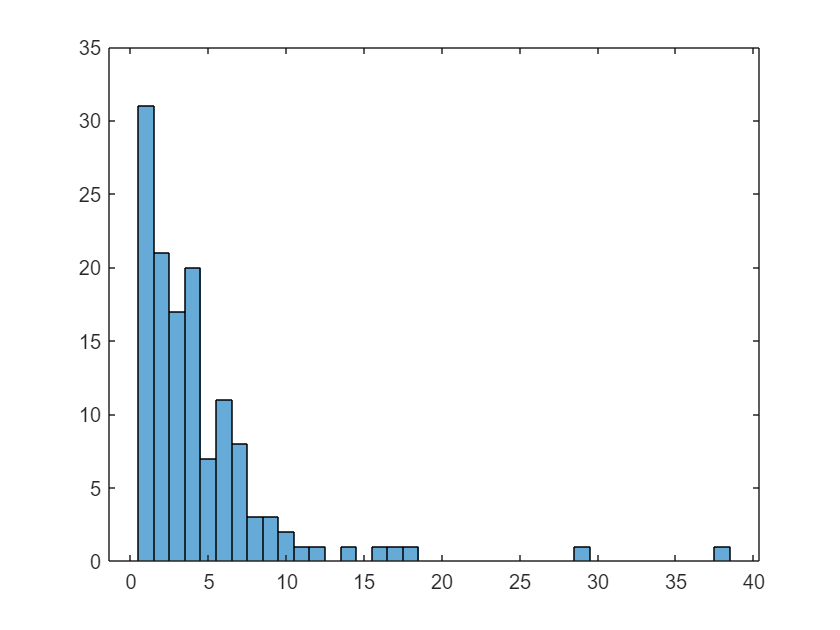


% what happened in 2008?
fish2008 = FishData_PLs(FishData_PLs.Year == 2008,"TNumFish");
figure
histogram(fish2008.TNumFish)

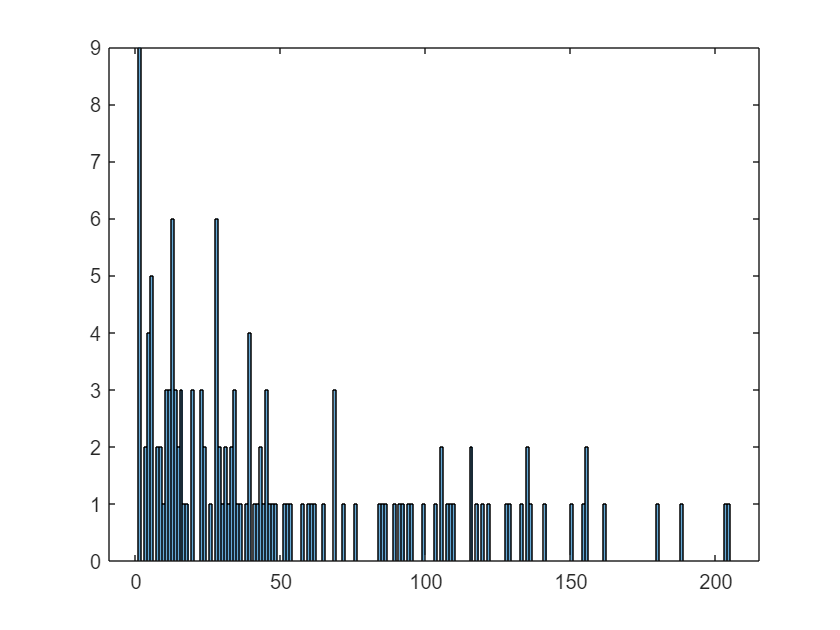

fish2002 = FishData_PLs(FishData_PLs.Year == 2002,"TNumFish");
figure
histogram(fish2002.TNumFish, 200)